# Kinematic DH Parameters for 3-link RPR arm

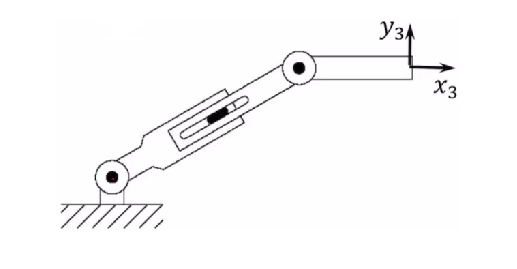

imshow(imread("./figures/RPR.png"))

### Robot Description

- **{r, p, r} : **r for revolute, p for prismatic

- **{0, 0, L_1} : **radius lenghts

- **{Pi/2, -Pi/2, 0} :** link twists

- **{0, q_2, 0} : **link offset rotation

- **{q1, 0, q3} : **joint rotation

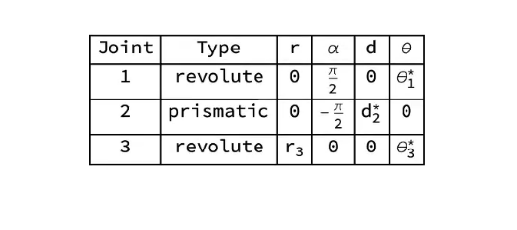

imshow(imread("./figures/DH.png"))

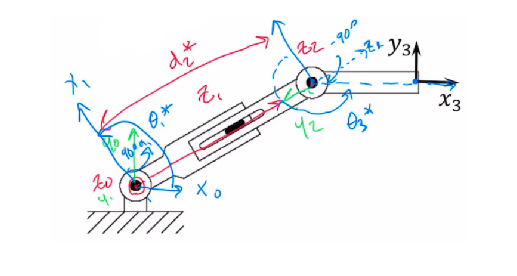

imshow(imread("./figures/annotated_RPR.png"))


$$A_i ={\textrm{Rot}}_{z,\theta_i } {\textrm{Trans}}_{z,d_i } {\textrm{Trans}}_{x,\alpha_i } {\textrm{Rot}}_{x,\alpha_i }$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i }  & 0 & 0\\
s_{\theta_i }  & c_{\theta_i }  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & \alpha_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 1 & 0\\
0 & c_{\alpha_i }  & -s_{\alpha_i }  & 0\\
0 & s_{\alpha_i }  & c_{\alpha_i }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i } c_{\alpha_i }  & s_{\theta_i } c_{\alpha_i }  & a_i c_{\theta_i } \\
s_{\theta_i }  & c_{\theta_i } c_{\alpha_i }  & -c_{\theta_i } s_{\alpha_i }  & a_i s_{\theta_i } \\
0 & s_{\alpha_i }  & c_{\alpha_i }  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The DH parameters define the geometry of how each rigid body attaches to its parent via a joint. The parameters follow a four transformation convention:

- $A$ — Length of the common normal line between the two *z*-axes, which is perpendicular to both axes

- $\alpha$ — Angle of rotation for the common normal

- $d$ — Offset along the *z*-axis in the normal direction, from parent to child

- $\theta$ — Angle of rotation for the *x*-axis along the previous *z*-axis

clc
clear
close all


syms t1 d2 Xe Ye ;

dhparams = [0   	 pi/2	    0   	t1 ;
            0	    -pi/2       d2      0  ;
            10	     0	        0	    pi-t1 ];


H0_1 = DH(dhparams(1,1), dhparams(1,2), dhparams(1,3), dhparams(1,4))
H1_2 = DH(dhparams(2,1), dhparams(2,2), dhparams(2,3), dhparams(2,4))
H2_3 = DH(dhparams(3,1), dhparams(3,2), dhparams(3,3), dhparams(3,4))

$$H0\_1 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & 0 & \sin\left(t_{1}\right) & 0\\ \sin\left(t_{1}\right) & 0 & -\cos\left(t_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$H1\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0_2 = H0_1*H1_2

$$H2\_3 = \left(\begin{array}{cccc} -\cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & -10\,\cos\left(t_{1}\right)\\ \sin\left(t_{1}\right) & -\cos\left(t_{1}\right) & 0 & 10\,\sin\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0_3 = H0_1*H1_2*H2_3

O1_x = simplify(H0_1(1,4))

$$H0\_2 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & d_{2}\,\sin\left(t_{1}\right)\\ \sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O1_y = simplify(H0_1(2,4))

$$H0\_3 = \left(\begin{array}{cccc} -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & 0 & -10\,{\cos\left(t_{1}\right)}^{2}-10\,{\sin\left(t_{1}\right)}^{2}+d_{2}\,\sin\left(t_{1}\right)\\ 0 & -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


O2_x = simplify(H0_2(1,4))

$$O1\_x = 0$$

O2_y = simplify(H0_2(2,4))

$$O1\_y = 0$$


O3_x = simplify(H0_3(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O3_y = simplify(H0_3(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


xeq = Xe == O3_x

$$O3\_x = d_{2}\,\sin\left(t_{1}\right)-10$$

yeq = Ye == O3_y

$$O3\_y = -d_{2}\,\cos\left(t_{1}\right)$$


S = solve([xeq yeq],[t1 d2])

$$xeq = \mathrm{Xe}=d_{2}\,\sin\left(t_{1}\right)-10$$

$$yeq = \mathrm{Ye}=-d_{2}\,\cos\left(t_{1}\right)$$

simplify(S.t1)
simplify(S.d2)

S = struct with fields:
    t1: [2×1 sym]
    d2: [2×1 sym]


$$ans = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right)\\ 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}+\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right) \end{array}\right)$$

t_1 = simplify(S.t1)

$$ans = \left(\begin{array}{c} -\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}\\ \sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100} \end{array}\right)$$

d_2 = simplify(S.d2)



$$t\_1 = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right)\\ 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}+\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right) \end{array}\right)$$

Xe = 0

$$d\_2 = \left(\begin{array}{c} -\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}\\ \sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100} \end{array}\right)$$

Ye = 40



Xe = 0

t_1 = eval(t_1)

Ye = 40

d_2 = eval(d_2)


O1_x = simplify(H0_1(1,4))

t_1 =    -0.2450
    2.8966


O1_y = simplify(H0_1(2,4))

d_2 =   -41.2311
   41.2311



O2_x = simplify(H0_2(1,4))
O2_y = simplify(H0_2(2,4))


$$O1\_x = 0$$

O3_x = simplify(H0_3(1,4))

$$O1\_y = 0$$

O3_y = simplify(H0_3(2,4))


$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

% t1 = deg2rad(180-104.511+90)

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$

% t3 = deg2rad(90-(180-104.511))
% d2 = sqrt(20^2+30^2)

$$O3\_x = d_{2}\,\sin\left(t_{1}\right)-10$$

$$O3\_y = -d_{2}\,\cos\left(t_{1}\right)$$

t1 = atan(3/2)+pi/2
d2 = sqrt(20^2+30^2)


t1 = t_1(2)
d2 = d_2(2)

t1 = 2.5536

d2 = 36.0555



O2_x = eval(O2_x)

t1 = 2.8966

O2_y = eval(O2_y)

d2 = 41.2311


O3_x = eval(O3_x)
O3_y = eval(O3_y)


O2_x = 10.0000

clf

O2_y = 40

link1 = line([0,O1_x],[0,O1_y]);
link2 = line([O1_x, O2_x],[O1_y, O2_y]);

O3_x = 8.8818e-15

link3 = line([O2_x, O3_x],[O2_y, O3_y]);

O3_y = 40

xlim([0 80])
ylim([0 80])

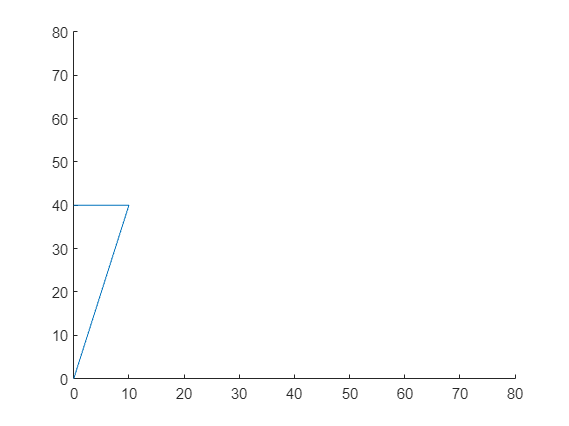

function [A] = DH(a,alpha,d,theta)

A = [cos(theta) -sin(theta)*round(cos(alpha))  sin(theta)*round(sin(alpha)) a*cos(theta);
     sin(theta)  cos(theta)*round(cos(alpha)) -cos(theta)*round(sin(alpha)) a*sin(theta);
     0           round(sin(alpha))             round(cos(alpha))            d ;

     0           0                             0                            1];
end